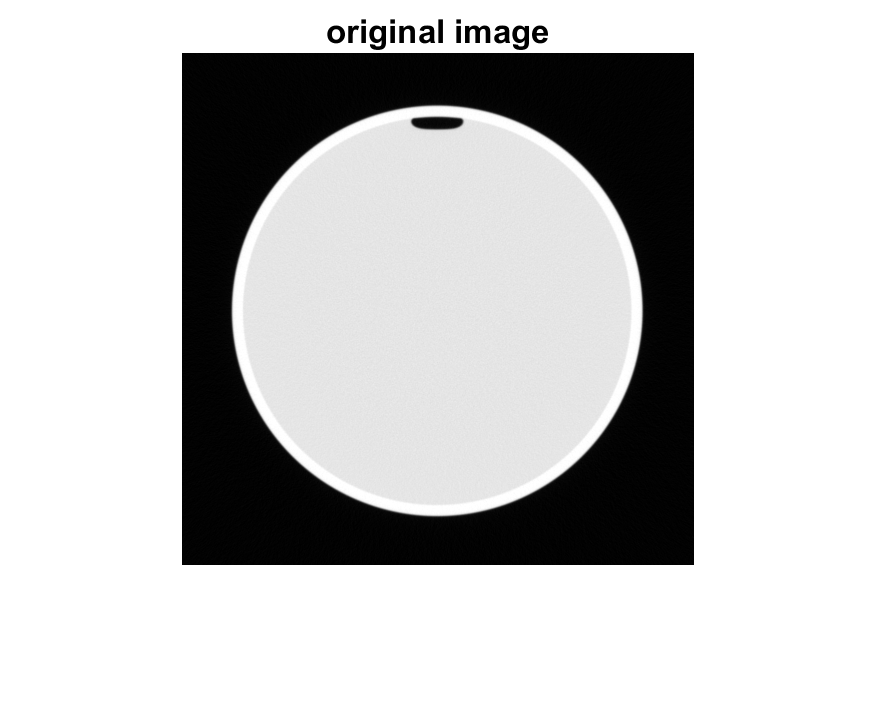

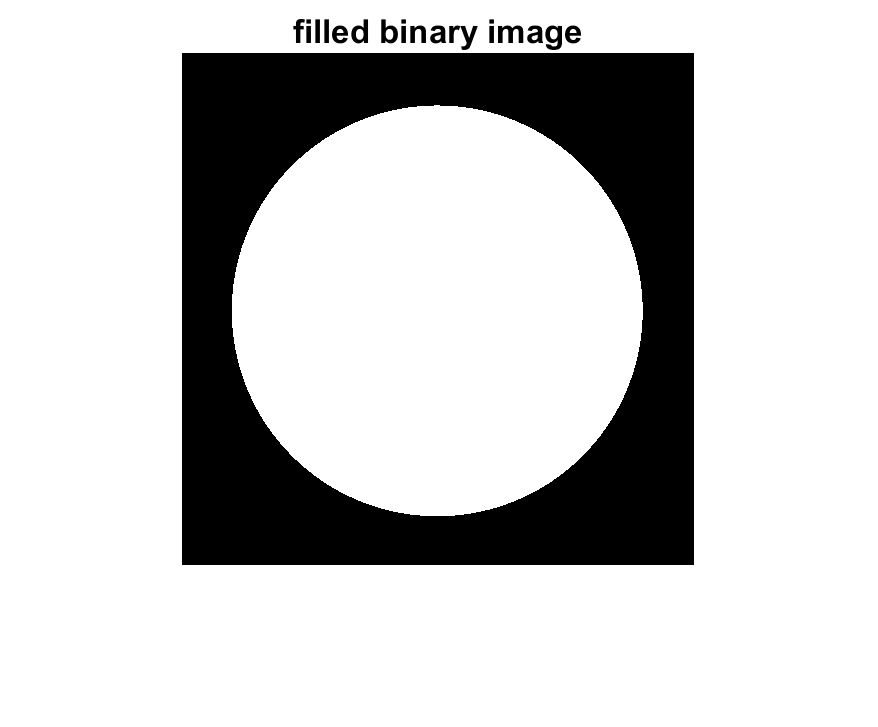

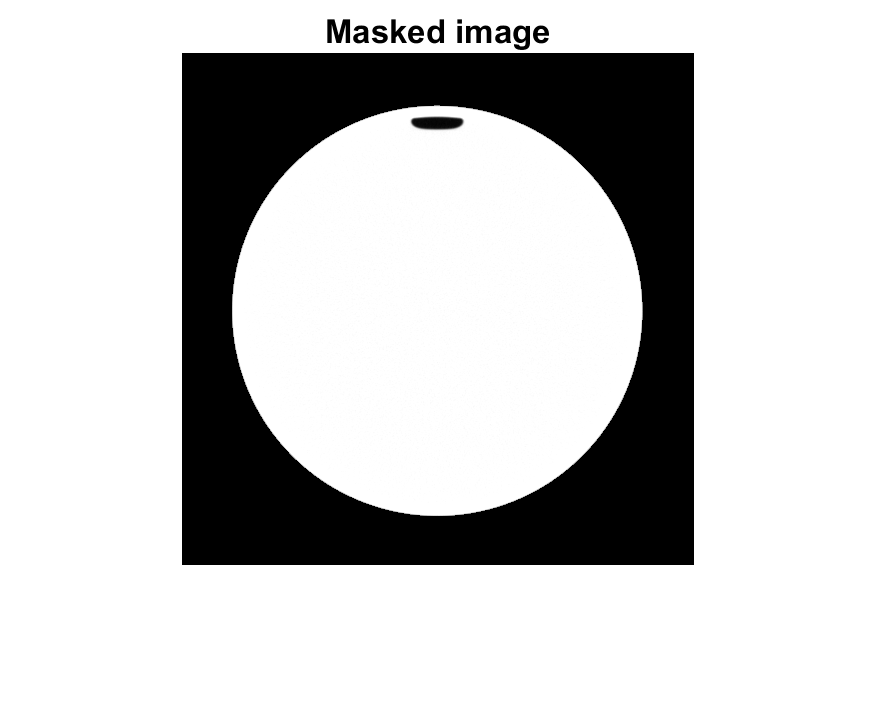

cd 'C:\Users\Public\'
filelist = dir('*.dcm');

area1=0.0;sum1=0;
for file = filelist'
    sum1=0;
    I = dicomread(file.name);
    figure, imshow(imadjust(I)), title('original image');
    bI=imbinarize(I);
    fbI=imfill(bI,'holes');
    cc=bwconncomp(fbI);
    numPixels = cellfun(@numel,cc.PixelIdxList);
    if numPixels > 1000  
        [biggest,idx] = max(numPixels);
        grain=false(size(I));
        grain(cc.PixelIdxList{idx})=true;
        figure,imshow(grain), title('filled binary image');
        metainfo = dicominfo(file.name);
        pixelarea=metainfo.PixelSpacing(1)*metainfo.PixelSpacing(2);
        area1=bwarea(grain)*pixelarea;
        test1=sum(grain(:))*pixelarea;
        equivdiameter=(sqrt(4*area1/pi))/10;
    end
    rescale_intercept= single(metainfo.RescaleIntercept);
    hadj=@(x) ((single(x)+rescale_intercept)/1000.) + 1.;
    masked_attens=arrayfun(hadj,I);
    masked_attens(~grain)=0;
    tot_pixel_atten_area =sum(masked_attens(:));
    area2=tot_pixel_atten_area*pixelarea;
    equiv_pix_attn_diam=(sqrt(4*area2/pi))/10;
    figure, imshow(imadjust(masked_attens)),title('Masked image');
end